
tic
%We initialize the values
Kp=0;
Ki=0;
Kd=0;
V=2.5; %volts
tmax=49; %seg
Va = repmat( V, [tmax,1] );
s=10;
step=2;
Tapprox=V+V/2.9;

%We create the noise factor
r=rand(tmax,1);
H = 0:tmax-1;
n=[H.' r];

%we start the loop of the simulations, 1000 iterations in total from
%kp,kd,ki = 0 to kp, kd, ki = 20.

diff2=2.5*50;
l=0;
while diff2 > Tapprox
        c=randi(50)/5;
        step= c;
        Kp=Kp+step;
        r=rand(tmax,1)*1.3;
        ans = sim('Simulation','ReturnWorkspaceOutputs','on');
        set_param('Simulation','SimulationCommand','update');
        l=l+1
        
        for i=1:49
            diff(i)=abs(ans.Curve(i)-Va(i));
        end
        diff1=sum(diff);

       if diff2 > diff1
           diff2=diff1;
           Kp2=Kp ;
           set_param('Simulation','SimulationCommand','update');
       end
       
       Kp=Kp2;
         
       c=randi(50)/5;
       step= c;
       Ki=Ki+step;
       r=rand(tmax,1)*1.3;
       ans = sim('Simulation','ReturnWorkspaceOutputs','on');
       set_param('Simulation','SimulationCommand','update');
       l=l+1
        
        for i=1:49
            diff(i)=abs(ans.Curve(i)-Va(i));
        end
        diff1=sum(diff);

       if diff2 > diff1
           diff2=diff1;
           Ki2=Ki ;
           set_param('Simulation','SimulationCommand','update');
       end
       
       Ki=Ki2;
       
        c=randi(50)/5;
        step= c;
        Kd=Kd+step;
        r=rand(tmax,1)*1.3;
        ans = sim('Simulation','ReturnWorkspaceOutputs','on');
        set_param('Simulation','SimulationCommand','update');
        l=l+1
        
        for i=1:49
            diff(i)=abs(ans.Curve(i)-Va(i));
        end
        diff1=sum(diff);

       if diff2 > diff1
           diff2=diff1;
           Kd2=Kd ;
           set_param('Simulation','SimulationCommand','update');
       end
       
       Kd=Kd2;
       
        
end

l = 1

l = 2

l = 3

l = 4

l = 5

l = 6

l = 7

l = 8

l = 9

l = 10

l = 11

l = 12

l = 13

l = 14

l = 15

l = 16

l = 17

l = 18

l = 19

l = 20

l = 21

l = 22

l = 23

l = 24

l = 25

l = 26

l = 27

l = 28

l = 29

l = 30

l = 31

l = 32

l = 33

l = 34

l = 35

l = 36

l = 37

l = 38

l = 39


Kp

Kp = 60.2000

Kd

Kd = 15.6000

Ki

Ki = 12

l

l = 39

diff2

diff2 = 3.3618

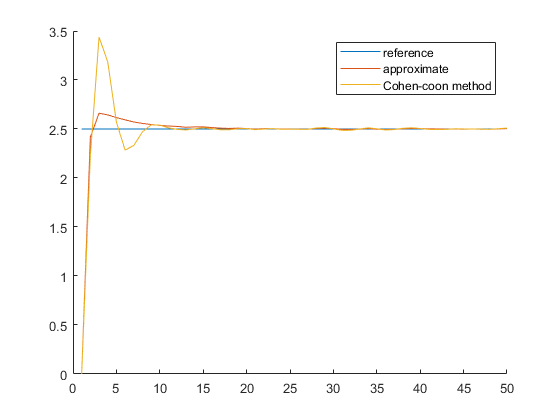


hold on
plot (Va(:))
plot(ans.Curve(:))
plot(ans.Curve1(:))

legend('reference', 'approximate', 'Cohen-coon method')